# MATLAB Deep Learning Toolbox

## MATLAB's  Deep Learning Toolbox

To use MATLAB's neural network software, we need to download the [Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html#net). The documentation for the shallow neural network can be found on [this page](https://www.mathworks.com/help/deeplearning/getting-started-with-deep-learning-toolbox.html), and there is a really cool GUI tool that covers each step of the training process (which can be called using `nnstart, `documentation found [here](https://www.mathworks.com/help/deeplearning/ref/nnstart.html)). However, we will go over training the same neural network we've trained in the last lecture using the command-line functions.

### Load the breast cancer image classification dataset

Let's load the breast cancer image classification dataset we've been using for the last two lectures. The MATLAB built-in functions process datasets where the features/target variables span the rows, while the observations span the columns.

clear all; rng(2);
load cancer_dataset.mat

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cancerInputs', cancerTargets(1, :)', ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

% Transpose all datasets
Xtrain = Xtrain'; Ytrain = Ytrain'; Xtest = Xtest'; Ytest = Ytest';

### Setting the shallow neural network architecture

Next, let's specify the neural network architecture for the shallow neural network, using the same architecture we've been using so far:

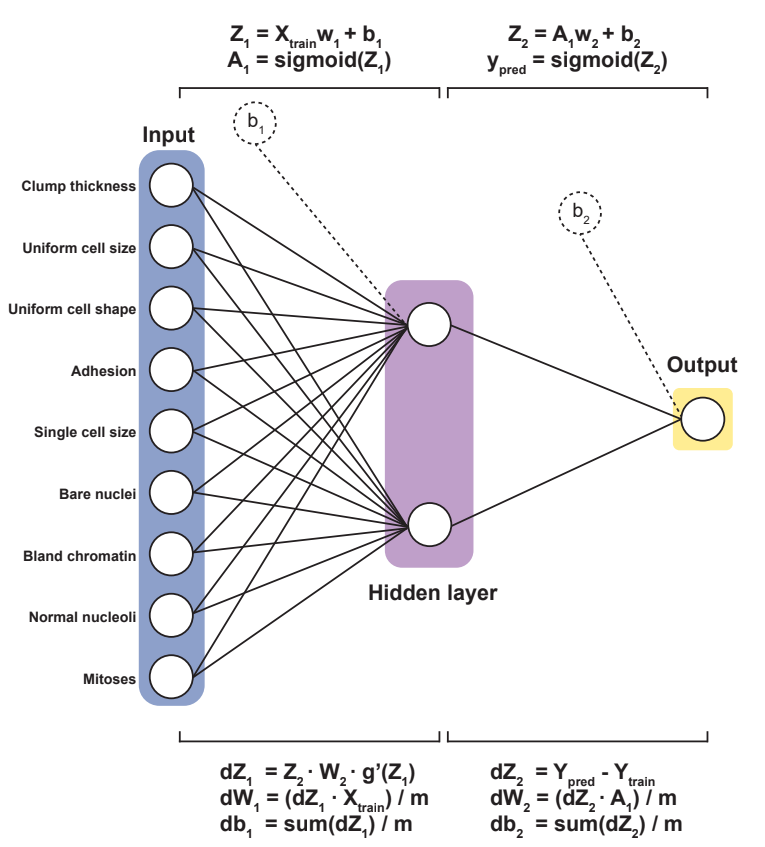

This can be done using the `feedforwardnet` function, which returns a structure consisting of the network values as fields.

Note that as a default, MATLAB uses the** Levenberg-Marquardt** algorithm, another optimization algorithm that tunes the model parameters to minimize the cost function. If you wanted to specify the optimization function as the gradient descent optimization algorithm, you can do so as the second argument in the `feedforwardnet` function. 

numOfActivationNodes = 2;         % 1 hidden layer with 2 activation nodes
optimizationFnc      = 'traingd'; % Gradient descent optimization algorithm
net                  = feedforwardnet(numOfActivationNodes, optimizationFnc)

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConne

### View the network structure with MATLAB's GUI

Let's view the network structure `net` using the `view` function, which utilizes MATLAB's GUI. 

view(net)

The popup screen should show you the following information:

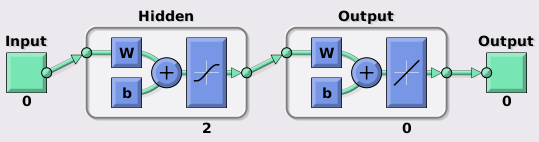

The numbers beneath each panel denotes the number of features (for the input/output) or the number of nodes in the network. Because we have not fitted the data using a training or testing set, the numbers below the input/output in the figure above are shown as 0. 

Note that this diagram is similar to the one we've been using to depict the network structure:

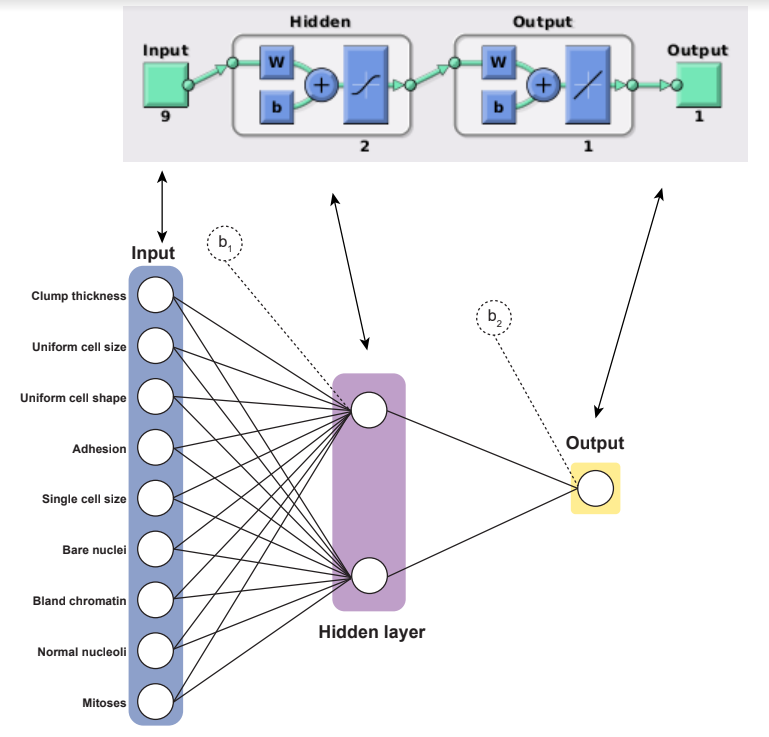

However, one main difference between the algorithm we wrote and MATLAB's algorithm is that MATLAB only performs a final linear combination from the hidden to the output layer, while we have been re-transforming the linear combination to probabilities using another `Sigmoid` activation function. 

### Setting up the network hyperparameters

Most of the hyperparameters can be modified by setting the fields in the `net` structure. We won't go over each individual hyperparameter here (the documentation to modify some training parameters can be found in this [link](https://www.mathworks.com/help/deeplearning/ref/traingda.html)), but we'll some of the more important ones.

#### Validation sets

To divide the data for training, validation, and testing, we can specifying some fields in the `net` structure we made from the `fitnet` function.

net.divideParam.trainRatio = 0.6; % Training set size
net.divideParam.testRatio  = 0.2; % Test set size
net.divideParam.valRatio   = 0.2; % Cross validation set size

During the training phase, if you input the entire dataset, it automatically splits the dataset into three groups: 60% training, 20% testing (holdout), and an additional 20% for cross validation accuracy determinination. 

#### Loss functions

By default, the loss function is specified as the mean squared error. We'll use the MATLAB default features, but if we wanted to compute classification errors using the cross entropy loss function, we need to specify the `crossentropy` function using the following syntax:

%net.performFcn             = 'crossentropy';
net.performFcn             = 'mse';

#### Epochs

The number of epochs can be specified by setting the `net.trainParam.epochs` parameter. While MATLAB performs 1000 epochs by default, we'll set it to 10,000 epochs just to ensure we'll fully train the model. 

net.trainParam.epochs      = 10000;

Note that MATLAB automatically performs **early stopping - **it stops training the model when the model error increases during an epoch. This is a nice feature to implement that helps the model avoid overfitting. 

### Training the shallow neural network

Let's now train the shallow neural network using the `train` function, which will also show the MATLAB GUI while the model is training. An example of the GUI is shown below.

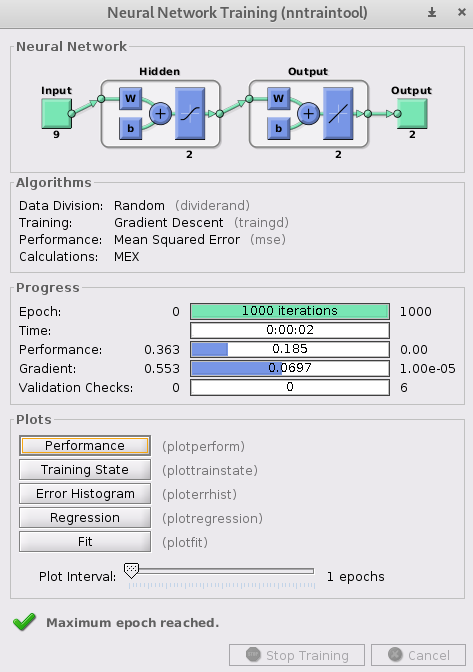

`train` takes in the network architecture we specified (`net)`, the `input` data, and the target labels `outputs`, and outputs the trained neural network (`trainedNet)`, as well as the computed metrics (`trainingRecord)`. 

[trainedNet, trainingRecord] = train(net, Xtrain, Ytrain)

trainedNet =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 23
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      in

trainingRecord = struct with fields:
        trainFcn: 'traingd'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×335 double]
          valInd: [1×112 double]
         testInd: [1×112 double]
            stop: 'Maximum epoch reached.'
      num_epochs: 10000
       trainMask: {[1×559 double]}
         valMask: {[1×559 double]}
        testMask: {[1×559 double]}
      best_epoch: 10000
            goal: 0
          states: {1×7 cell}
           epoch: [1×10001 double]
            time: [1×10001 double]
            perf: [1×10001 double]
           vperf: [1×10001 double]
           tperf: [1×10001 double]
        gradient: [1×10001 double]
        val_fail: [1×10001 double]
       best_perf: 0.0225
      best_vperf: 0.0503
      best_tperf: 0.0269


### Computing model predictions and evaluating model performance

First, we'll compute our predictions using the test dataset. The trained neural network `trainedNet` also acts as function to compute predictions. We can use the following syntax to compute the predicted Y values from the test set.

ypred = trainedNet(Xtest)

ypred =    -0.0992    0.0179    1.0105    0.3424    0.9180    1.0113    0.2061    0.0652    1.0113    1.0152    0.0065    0.0188    1.0073    0.0097    0.3791    0.9813    1.0125    0.0470   -0.0169    1.0152   -0.0345    0.0415    0.0387    0.9655    0.9908    0.9455    0.0925    0.9672    0.0022    0.0545    0.2487    0.9767    0.0020    0.9983    0.9659    0.0273   -0.1891    1.0109    0.9983    1.0125    0.0514    1.0080    0.9510    1.0073    1.0080    1.0031    0.8407    0.2494    1.0073    0.0340


From here we can use the methods we described previously to evaluate the model. To evaluate the model's performance, we can use the built-in `perform` function, which has the following syntax:

error = perform(trainedNet, Ytest, Ypred)

trainingAccuracy = 0.9960

holdOutAccuracy = 0.9607

CVAccuracy = 0.9598

### Plotting model metrics 

#### Cost Curves

We can plot the cost curves we've generated previously using the `plotperf` function. Note that the error is in log-scale, unlike the plots we have computed previously. Additionally, it plots the training error, test error, and validation error as separate cost curves.

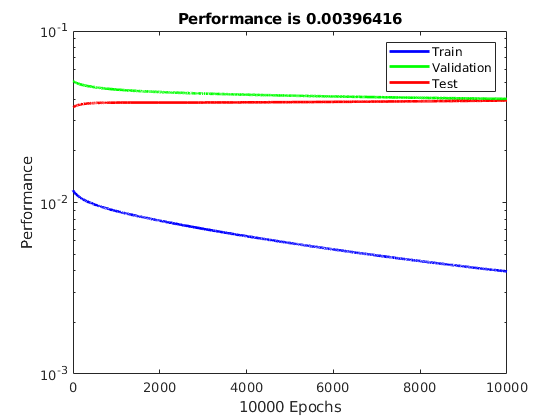

plotperf(trainRecordTest)

### Confusion matricies

Now plot a confusion matrix of the model holdout using the `confusionmat` and the `confusionchart` functions..

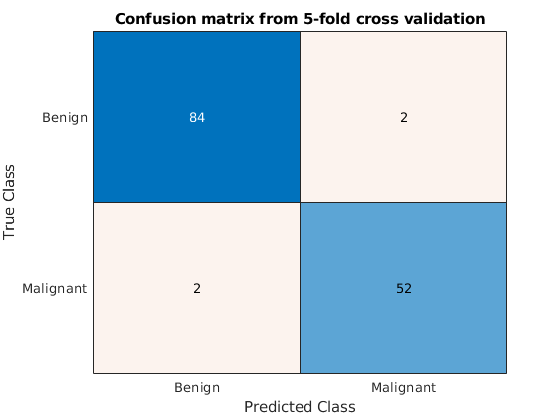

cm = confusionmat(round(ypred), Ytest);
figure; labels = {'Malignant', 'Benign'};
confusionchart(cm, labels)
title('Confusion matrix from 5-fold cross validation');

TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)

malignant_precision = 0.9630

malignant_recall    = (TP) / (TP + FN)

malignant_recall = 0.9630

benign_precision    = (TN) / (TN + FP)

benign_precision = 0.9767

benign_recall       = (TN) / (TN + FN)

benign_recall = 0.9767

average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

average_accuracy = 0.9714

## Neural Networks for k-class classification problems

Now that we have seen how a shallow neural network works with a binary classification problem, let's extend our approach to a k-class classification problem to the Cleveland heart disease dataset. 

### Load the cleveland dataset

Recall that the dataset has 5 different classes for disease heart disease severity, where 0 is no disease and 4 is high risk. 

clear all; cleveland = readtable('cleveland.xlsx')

cleveland = 303×14 table
    Age    SEX    chestPain    restingBP    cholest    highBloodSugar    ECG    maxHR    angina0    ECGDepression    slopeST    flouroscopy    thalliumTest    diseaseSeverity
    ___    ___    _________    _________    _______    ______________    ___    _____    _______    _____________    _______    ___________    ____________    _______________

    63      1         1           145         233            1            2      150        0            2.3            3            0              

First, we need to split the dataset into a training and testing set.

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cleveland(:, 1:end-1), cleveland(:, end), ...
    trainingSize, randomstate);

Next, we need to standardize the dataset:

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

Finally, let's expand our single column to an array, where the value 1 in each column corresponds to whether or not the observation belongs to a specific class. 

% Initialize our arrays. Because there are 5 classes, we need to make an n
% x 5 array
kclasses  = length(unique(Ytest));
tmpYtrain = zeros(size(Ytrain, 1), kclasses);
tmpYtest  = zeros(size(Ytest, 1), kclasses);

% Make new response arrays. Note that the classes were originally between 0
% and 4.
for i = 1:kclasses
    tmpYtrain(:, i) = (Ytrain == (i - 1));
    tmpYtest(:, i)  = (Ytest == (i - 1));
end
Ytrain = tmpYtrain; Ytest = tmpYtest; % Set the new Ytrain and Ytest variables
Ytrain                                % Show only Ytrain

We need to transpose the dataset so that the features span the rows and the columns span the observations.

Xtrain = Xtrain'; Ytrain = Ytrain'; Xtest = Xtest'; Ytest = Ytest';

Ytrain =      1     0     0     0     0
     0     0     1     0     0
     0     1     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     0     0     0     1     0
     0     1     0     0     0
     1     0     0     0     0
     1     0     0     0     0


### Initialize model hyperparameters

Next, let's initialize some model hyperparameters in order to train the model, including the optimization algorithm, network structure, and number of epochs.

numOfActivationNodes = 5;                                                     % 1 hidden layer with 5 activation nodes
optimizationFnc      = 'traingd';                                             % Gradient descent optimization algorithm
net                  = feedforwardnet(numOfActivationNodes, optimizationFnc); % Construct a shallow feedforward neural network with 5 activation nodes

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConne

net.performFcn             = 'mse';                                            % Set the cost function to be mean squared error (default param)
net.divideParam.trainRatio = 0.7;                                              % Training set size = 70%
net.divideParam.testRatio  = 0.2;                                              % Test set size = 20%
net.divideParam.valRatio   = 0.1;                                              % Cross validation set size = 10%
net.trainParam.epochs      = 10000;                                            % Number of epochs = 10,000

### Train the shallow feedforward neural network

Finally, we can train the neural network and output the trained model, as well as model metrics using the `train` function. 

[trainedNet, trainingRecord] = train(net, Xtrain, Ytrain)                      % Train the model

trainedNet =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 100
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      i

trainingRecord = struct with fields:
        trainFcn: 'traingd'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×170 double]
          valInd: [1×24 double]
         testInd: [1×48 double]
            stop: 'Maximum epoch reached.'
      num_epochs: 10000
       trainMask: {[5×242 double]}
         valMask: {[5×242 double]}
        testMask: {[5×242 double]}
      best_epoch: 10000
            goal: 0
          states: {1×7 cell}
           epoch: [1×10001 double]
            time: [1×10001 double]
            perf: [1×10001 double]
           vperf: [1×10001 double]
           tperf: [1×10001 double]
        gradient: [1×10001 double]
        val_fail: [1×10001 double]
       best_perf: 0.0886
      best_vperf: 0.1104
      best_tperf: 0.1250


ypred =     0.8202    0.5150    0.8823    0.8144   -0.1304    0.8895   -0.0805    0.6768    0.3214    0.8791    0.3616   -0.0889    0.7032   -0.2952    0.9262    0.2730    0.0579    0.8769    0.9214    0.8550    0.7758    0.5397    0.5522    0.6328    0.0131    0.8632    0.5070    0.1558    0.8577    0.4155    0.1086    0.0056    0.8280    0.3619    0.2265    0.4717    0.3954    0.7563    0.9237    0.1720    0.3717    0.0794    0.0231    0.9088    0.1252    0.8788    0.8409    0.7874    0.6637    0.2509
    0.2112    0.1907    0.1416   -0.1642    0.3750    0.0659    0.3978    0.2244    0.1595    0.1366    0.1617    0.3578   -0.0800    0.3741    0.1409    0.2995    0.4883    0.1403    0.1331    0.1424    0.1075    0.1289    0.1712    0.1052    0.1507    0.1352    0.1315    0.2354   -0.0192    0.1981    0.2337    0.3648    0.0347    0.2224    0.3634    0.1263    0.3722    0.2096    0.0780    0.3114    0.2389    0.3238    0.1176    0.1615    0.1368    0.0502    0.1045    0.4502    0.0864 

### Computed predicted label values using the trained neural network

Let's now output our predicted values using the `trainedNet` object, which acts as a function as well.

ypred = trainedNet(Xtest)

Now that we have the predicted values from the neural network value, we need to label encode these values. One natural question that you may be wondering is, how do we label encode these values for 5 classes? We'll discuss the generalized form of the log-loss activation function, which is known as the **softmax activation function**.  

### The softmax activation function

#### Intuition of the softmax activation function

The sigmoid activation function expression transforms values into probabilities using the following expression:$A=\frac{1}{1+e^{-Z} }$

If Z is very large, the expression moves towards 1, while if Z is very small, the expression moves towards 0. This allows us to transform values to assume a binary distribution, and gives us a natural decision boundary: $p=0\ldotp 5$. 

The question now then, is how do we draw multiple decision boundaries for a k-class problem? One method is to compute a normalized score for each observation with respect to each class:

$y_{\mathrm{pred}} =\frac{e^{Z_k } }{\underset{k}{\sum e^{Z_k } } }$ where $k$ denotes a specific class. 

This normalizes the outputs from the neural network from 0 to 1. Then, we choose to label encode an observation to a particular class with the maximum value. This is known as the **softmax** activation function, and it is the generalized form of the log-loss activation function for $k$-class classification problems. A schematic of the softmax activation function is shown below:

{INSERT FIGURE OF THE SOFTMAX ACTIVATION FUNCTION}

The code block below finds the maximum value in each column, and sets it equal to 1, while the other values are set to 0. Then we will label encode each class in the predicted values and the test set with value of 1 through 5 (1 = class 1, 2 = class 2, etc). 

% Softmax activation function
ypred = exp(ypred) ./ sum(exp(ypred))

% Set maximum value in each column as 1, while the other values are set to
% 0
ypred(ypred == max(ypred)) = 1;
ypred(ypred ~= max(ypred)) = 0;

% Label encode each class in the predicted and test dataset using a for loop
for i = 1:5
    ypred(i, ypred(i, :) == 1) = i;
    Ytest(i, Ytest(i, :) == 1) = i;
end

Finally, let's evaluate the performance of the model using the `perform` function.

error = perform(trainedNet, Ytest, Ypred)

trainRecordTest = struct with fields:
        trainFcn: 'traingd'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×43 double]
          valInd: [25 28 31 45 52 60]
         testInd: [1 11 14 21 23 24 40 44 47 54 58 61]
            stop: 'Validation stop.'
      num_epochs: 3433
       trainMask: {[5×61 double]}
         valMask: {[5×61 double]}
        testMask: {[5×61 double]}
      best_epoch: 3427
            goal: 0
          states: {1×7 cell}
           epoch: [1×3434 double]
            time: [1×3434 double]
            perf: [1×3434 double]
           vperf: [1×3434 double]
           tperf: [1×3434 double]
        gradient: [1×3434 double]
        val_fail: [1×3434 double]
       best_perf: 0.7549
      best_vperf: 1.2870
      best_tperf: 0.8824


training_MSE = 0.7549

test_MSE = 0.8824

validation_MSE = 1.2870

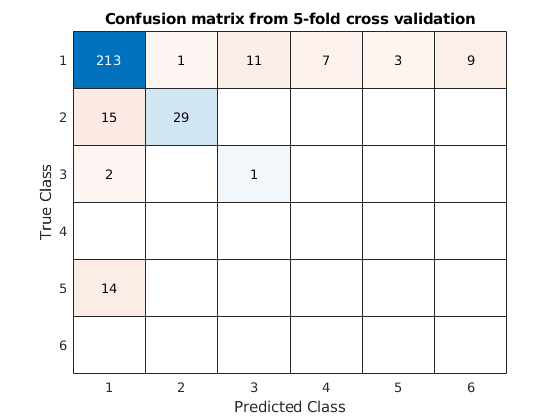

cm = confusionmat(ypred(:), Ytest(:));
figure; 
confusionchart(cm)
title('Confusion matrix from 5-fold cross validation');

average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

average_accuracy = 0.7967

### Training the k-class shallow neural network

Let's now run our k-class classification problem using the shallow neural network we constructed.

% Train the shallow neural network model
model = SNN(Xtrain, Ytrain, hyperparameters)
ypred = mdlPredict(model, Xtest, 'SNN')

## Neural Networks for regression

Let's now apply a shallow neural network to a regression problem, where we will use the entire glioblastoma dataset to predict the survival rate (`SurvivalDaysOS)` for 12 out of the 60 patients (20% of the dataset).

clear all; load gbm.mat
hyperparameters.numOfActiveNodes = 500;   hyperparameters.alpha = 0.05;
hyperparameters.epoch            = 500;   hyperparameters.actFnc = 'Leaky ReLU';
hyperparameters.randomstate      = 2;

X
Y
% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
%mu = mean(Xtrain); sigma = std(Xtrain);
%Xtrain = (Xtrain - mu) ./ sigma; 
%Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

model = SNN(Xtrain, Ytrain, hyperparameters)

We will perform the same computations as we have previously. However, we need to change our algorithm by making the following changes:

- We don't compute transform the values into probabilities from the hidden layer to the output layer. Instead, we should use the **ReLU** or **leaky ReLU** activation functions.

- To evaluate the cost error, we can use the **mean-squared error** loss function to compute the distance between the predicted and training value. 

## Deep feed-forward neural networks and deep learning

Up until this point, we have only been dealing with a single hidden layer. What if we wanted to extend our neural network's capacity to handle $L$hidden layers to train a more non-linear model? 

We can generalize the approach we have used to construct the shallow neural network using the generalized forward and backward propagation algorithm, shown below. 

#### The general forward propagation algorithm

$Z^{\left\lbrack L\right\rbrack } =A^{\left\lbrack L-1\right\rbrack } w^{\left\lbrack L\right\rbrack } +{b\;}^{\left\lbrack L\right\rbrack }$. Note that $A^{\left\lbrack 1\right\rbrack } =X$.

$A^{\left\lbrack L\right\rbrack } =g^{\left\lbrack L\right\rbrack } \left(Z^{\left\lbrack L\right\rbrack } \right)$, where $g^{\left\lbrack L\right\rbrack }$ is a non-linear function of our choosing at an $L^{\textrm{th}}$ layer.

#### The general backward propagation algorithm

${\textrm{dZ}}^{\left\lbrack L\right\rbrack } ={\textrm{dA}}^{\left\lbrack L\right\rbrack } \cdot$$g^{\prime \left\lbrack L\right\rbrack } \left(Z^{\left\lbrack L\right\rbrack } \right)$, where ${\textrm{dA}}^{\left\lbrack \textrm{end}\right\rbrack } =Y_{\textrm{train}} -Y_{\textrm{pred}}$ and $g^{\prime \left\lbrack L\right\rbrack }$ is the derivative term for the activation function at layer $L$.


$${\textrm{dA}}^{\left\lbrack L-1\right\rbrack } =W^{\left\lbrack L\right\rbrack } {\textrm{dZ}}^{\left\lbrack L\right\rbrack }$$



$${\textrm{dW}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\left({{\textrm{dZ}}^{\left\lbrack L\right\rbrack } A}^{\left\lbrack L-1\right\rbrack } \right)$$



$${\mathrm{db}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\left({\mathrm{dZ}}^{\left\lbrack L\right\rbrack } \right)$$


A non-elegant way of doing this using `for loops` for each layer is shown in the `DNN.mlx` script provided. However, we'll mostly discuss how to construct a deep neural network using MATLAB's deep learning toolbox.

### Deep neural networks from the Deep Learning Toolbox

MATLAB has made it easy to construct deep neural networks by simply using the `trainNetwork` function. It takes in the datasets $X_{\textrm{train}}$ and $Y_{\textrm{train}}$, the network architecture as the third argument, and the hyperparameter specifications in the 4th argument. We'll use the breast cancer imaging dataset to train and test this deep neural network.

clear all; rng(2);
load cancer_dataset.mat

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cancerInputs', cancerTargets(1, :)', ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

% Transpose all datasets
Xtrain = Xtrain'; Ytrain = Ytrain'; Xtest = Xtest'; Ytest = Ytest';

For a classification problem, the labels need to be transformed to a categorical data type to use MATLAB's `trainNetwork` function:

Ytrain = categorical(Ytrain); Ytest = categorical(Ytest);

Now, we need to specify the neural network architecture. We will store the network as an array called `layers`. We'll be constructing a deep neural network that has the following structure:

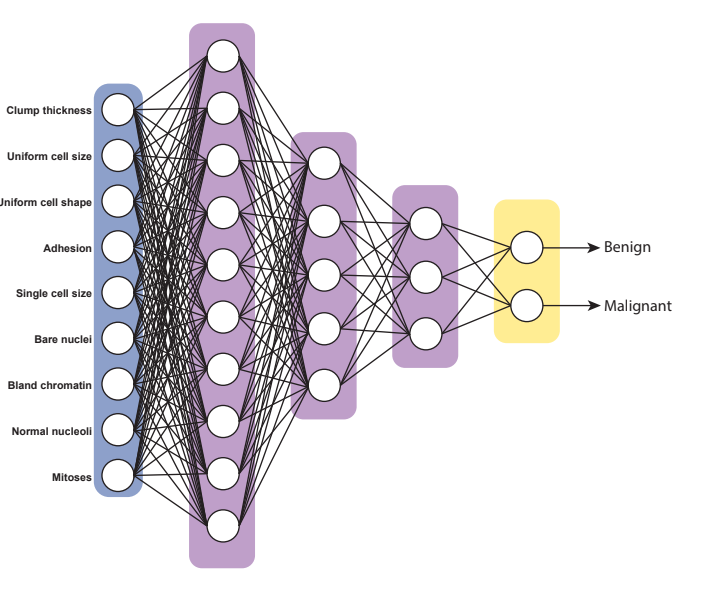

**There are 4 components we need to specify in the **`layer`** array:**

- **Input data layer**: the specific function differs on the data type inputed. For numerical data, the `sequenceInputLayer` is the appropriate function, which needs the number of features as the parameter.

- **Hidden layer architecture**: the specific architecture needed to design a feedforward neural network is the `fullyConnectedLayer`, which needs the number of activation nodes as the first parameter. The `WeightsInitializer` and `BiasInitializer` parameters tell the function how to initialize the parameters, using small random numbers from a normal distribution.

- **Activation function**: Between each `fullyConnectedLayer` is the activation function. The `softmaxLayer` is the activation function we will use.

- **Classification layer** (optional): The `classificationLayer` transforms the values to their predicted labels.

% Specify neural network architecture
layers = [...
    
    sequenceInputLayer(size(Xtrain, 1)), ...            % Input data layer

    fullyConnectedLayer(10, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 1
    
    fullyConnectedLayer(5, ...                         % Hidden layer 2 with 5 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 2
    
    fullyConnectedLayer(3, ...                          % Hidden layer 3 with 3 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 3
    
    classificationLayer ...                             % Label encode
]

Next, we have to specify the model hyperparameters. The `trainingOptions` function creates a model object that lets you feed in the hyperparameters into the neural network function. The specific arguments we will use are shown below.

% Spcify hyperparameters for neural network
options = trainingOptions(...
    'sgdm', ...                                   % Stochastic gradient descent
    'MaxEpochs', 500, ...                         % Maximum number of epochs to train algorithm
    'ValidationData', {Xtest, Ytest}, ...         % Dataset to use as the validation set
    'ValidationFrequency', 30, ...                % Frequency to validate the network at regular intervals
    'Verbose', true, ...                          % Outputs information about training 
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress' ...              % Show plots for every epoch
);                

Finally, let's train the neural network using the `trainNetwork` function, which allows us to train other deep neural network architectures. For more information on other neural networks you can train using this function, you can [read the documentation](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html).

[dnn, trainingInfo] = trainNetwork(Xtrain, Ytrain, layers, options)

The plot shown in the popup shows the accuracy and cost of training the neural network as a function the number of epochs, and shows the generation of the accuracy / cost curves in real time. 

To make predictions using the deep neural network model, we can use the built-in `predict` function, which returns the class probabilites.

ypred_dnn = predict(dnn, Xtest)

Let's plot the final confusion matrix for the deep feedforward neural network:

cm = confusionmat(categorical(round(ypred_dnn(2, :))), Ytest);
figure; labels = {'Malignant', 'Benign'};
confusionchart(cm, labels)
title('DNN confusion matrix from 5-fold cross validation');
TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)
malignant_recall    = (TP) / (TP + FN)
benign_precision    = (TN) / (TN + FP)
benign_recall       = (TN) / (TN + FN)
average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

## Summary

We've learned MATLAB's functions for training neural networks, and applied them to k-class classification problems and regression problems. Finally, we covered how to use MATLAB's deep neural network toolbox to train a deep neural network. 

In the final part of this lecture series, we'll discuss potential difficulties in training neural networks, strategies to address these potential difficulties, and how to optimize the training phase using parallel computing and hyperparameter optimization.

### Built-in MATLAB functions

`feedforwardnet:           `Initializes a feedforward neural network structure.

`plotperf:                 `Plots the cost curves from training a neural network.

`train:                    `Trains a shallow / feedforward neural network object.

`classificationLayer:      `Computes the cross entropy loss for multi-class classification problems.

`softmaxLayer:            `  Creates a softmax activation function layer for binary- and multi-classification problems.

`sequenceInputLayer:       `Stores the input dataset $X_{\mathrm{train}}$ as a MATLAB object for the `trainNetwork` function.

`fullyConnectedLayer:      `Creates a single hidden layer object for the` trainNetwork `function.

`trainingOptions:          `Creates an object used in the `trainNetwork` function that specifies the neural network hyperparameters.

`trainNetwork:             `Trains (among other network structures) a deep feedforward neural network.

`confusionmat:             `Automatically computes a confusion matrix for each class.

`confusionchart`:                         Plots the confusion matrix from `confusionmat.`

### Custom MATLAB functions

`trainTestSplit:           `Splits an input ($X$) and output ($Y$) dataset into a training $\left(X_{\textrm{train}} {,\;Y}_{\textrm{train}} \right)$ and testing $\left(X_{\textrm{test}} {,\;Y}_{\textrm{test}} \right)$ dataset